close all;
clear;
clc;
rng(0);

## Import data from csv files

opts = detectImportOptions('/MATLAB Drive/Running data.csv');
opts.VariableNamingRule = 'preserve';
prc = readtable('Running data.csv',opts);
opts = detectImportOptions('/MATLAB Drive/html/PM final project/MKRT- RF.csv');
opts.VariableNamingRule = 'preserve';
sprf = readtable('/MATLAB Drive/html/PM final project/MKRT- RF.csv',opts);

## Establish data structure

%Timestamps (1 DF lost)
dates = datetime(prc.Date(2:end));
% Names of risky assets
alist = prc.Properties.VariableNames(2:end);
% Risky asset prices
aprc = prc(:,alist).Variables;
%Compute risky asset returns
artn = tick2ret(aprc);
% S&P 500 returns (1 DF lost)
brtn = sprf.SPRTRN(2:end);
% Risk free rate (in %, 1 DF lost)
rf = sprf.RF(2:end)/100;

## Calculate annualised statistics

%Assume 252 working days in a year
scale = 252;
% Annualised daily mean asset return
amean = scale*mean(artn);
% Volatility of asset returns
avol = sqrt(scale)*std(artn);
% convert daily returns to annual returns for S&P
bmean = scale*mean(brtn); 
% annualized volatility for S&P
bvol = sqrt(scale)*std(brtn); 
rmean = mean(rf); 
rvol = std(rf);

## Set up portfolio objects

% one with asset return, the other with active return
% https://uk.mathworks.com/help/finance/portfolio.html
p = Portfolio('AssetList', alist, 'RiskFreeRate',rmean/252);
 % Set up portfolio constraints with nonnegative weights that sum to 1
p = setDefaultConstraints(p);
% excess return wtr benchmark = S&P500
ertn = artn-brtn; 
% Estimate mean and covariance of asset returns from data
ap = estimateAssetMoments(p,artn,'missingdata',false); 
ep = estimateAssetMoments(p,ertn,'missingdata',false);
% The default value for 'MissingData' is false which removes all samples with NaN values. If, however, 'MissingData' is set to true, estimateAssetMoments uses the ECM algorithm to estimate asset moments.

## **Optimization using CVaR**

% CVaR
nScenario = 2000;
simulationMethod = 'Normal'

simulationMethod = 'Normal'

alistStr = strjoin(alist, ',');
symbol = strsplit(alistStr,',');
%check the histogram of returns
plotAssetHist(symbol,artn)

AssetScenarios = mvnrnd(mean(artn),cov(artn),nScenario);
p1 = PortfolioCVaR('Scenarios', AssetScenarios);
p1 = setDefaultConstraints(p1); 
p1 = setProbabilityLevel(p1, 0.95);
%Check the histogram of asset scenarios
plotAssetHist(symbol,AssetScenarios)
% Plot efficient frontier and calculate portfolio weights
figure;
w1 = estimateFrontier(p1);
plotFrontier(p1,w1);
figure;
plotWeight(w1, symbol, 'CVaR Portfolio');
legend(symbol);

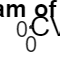

%% Visualize histogram of portfolio returns
portNum = 3; % Select port number in figure above
plotCVaRHist(p1, w1, artn, portNum, 50)

% Mean-variance
p2 = Portfolio;
p2 = estimateAssetMoments(p2, artn);
p2 = setDefaultConstraints(p2);
w2 = estimateFrontier(p2);

% CVaR vs Mean-Variance Portfolio Optimization
pRet1 = estimatePortReturn(p1,w1);
pRisk1 = estimatePortRisk(p1,w1);
pRet2 = estimatePortReturn(p1,w2);
pRisk2 = estimatePortRisk(p1,w2);
[M,I]=max(pRet1./pRisk1);

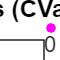

plot(pRisk1,pRet1,'-r',pRisk2, pRet2,'--b')
hold on
scatter(pRisk1(I),pRet1(I),12,'m','Filled');
title('Efficient Frontiers (CVaR VS Mean-Variance)');
xlabel('Conditional Value-at-Risk of Portfolio');
ylabel('Mean of Portfolio Returns');
legend({'CVaR','Mean-Variance'},'Location','southeast')
grid on;

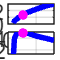

subplot(2,1,1)
plot(pRisk1, pRet1, 'LineWidth',2, 'color', 'b');
hold on
scatter(pRisk1(I),pRet1(I),12,'m','Filled');
grid on;
subplot(2,1,2)
plot(pRisk1, pRet1./pRisk1, 'LineWidth',2, 'color', 'b');
hold on
scatter(pRisk1(I),pRet1(I)/pRisk1(I),12,'m','Filled');
grid on;

nScenario = 20000;
AssetScenarios = mvnrnd(mean(artn),cov(artn),nScenario);
p1 = PortfolioCVaR('Scenarios', AssetScenarios);
p1 = setDefaultConstraints(p1); 
p1 = setProbabilityLevel(p1, 0.95);
w1 = estimateFrontier(p1);
% Mean-variance
p2 = Portfolio;
p2 = estimateAssetMoments(p2, artn);
p2 = setDefaultConstraints(p2);
w2 = estimateFrontier(p2);

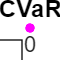

% CVaR vs Mean-Variance Portfolio Optimization
pRet1 = estimatePortReturn(p1,w1);
pRisk1 = estimatePortRisk(p1,w1);
pRet2 = estimatePortReturn(p1,w2);
pRisk2 = estimatePortRisk(p1,w2);
[M,I]=max(pRet1./pRisk1);

figure(14)
plot(pRisk1,pRet1,'-r',pRisk2, pRet2,'--b')
hold on
scatter(pRisk1(I),pRet1(I),12,'m','Filled');
title('Efficient Frontiers (CVaR VS Mean-Variance)');
xlabel('Conditional Value-at-Risk of Portfolio');
ylabel('Mean of Portfolio Returns');
legend({'CVaR','Mean-Variance'},'Location','southeast')
grid on;

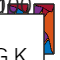

plotWeight2(w1, w2, symbol)